ACTIVIDAD 7

DANIEL CASTILLO LÓPEZ

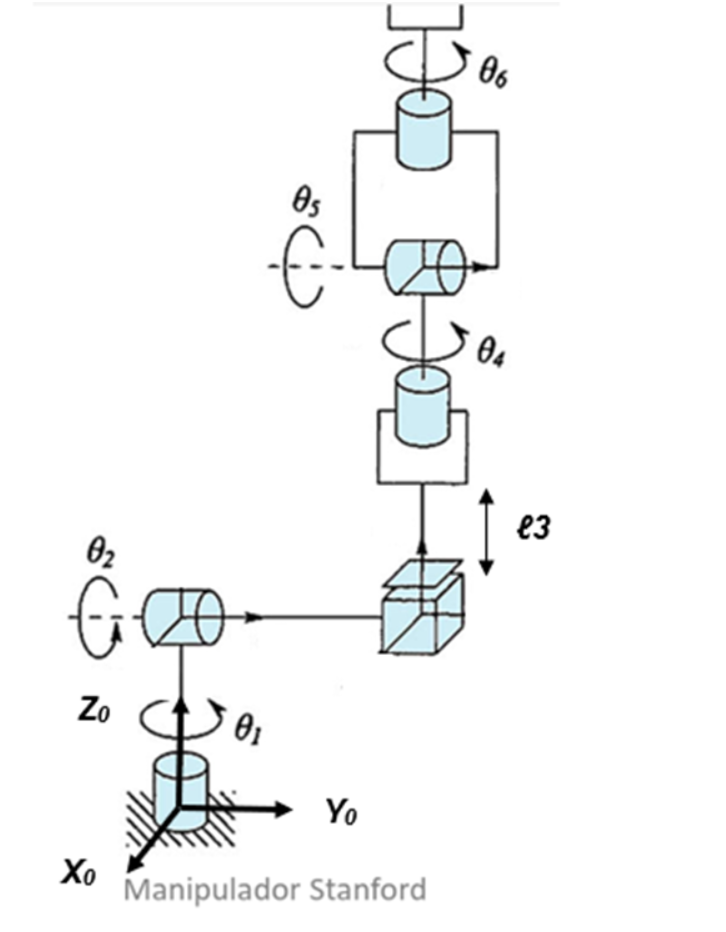

clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) l3(t) th4(t) th5(t) th6(t) t   %Angulos de cada articulación
syms th1p(t) th2p(t) l3p(t) th4p(t) th5p(t) th6p(t)   %Velocidades de cada articulación
syms th1pp(t) th2pp(t) l3pp(t) th4pp(t) th5pp(t) th6pp(t)  %Aceleraciones de cada articulación
syms m1 m2 m3 m4 m5 m6 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 Ixx4 Iyy4 Izz4 Ixx5 Iyy5 Izz5 Ixx6 Iyy6 Izz6   %Masas y matrices de Inercia
syms l1 l2 l4 l5 l6 lc1 lc2 lc3 lc4 lc5 lc6   %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

Creremos los vectores de coordenadas y se configura el robot con dos articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y  1 prismático

RP=[0 0 1 0 0 0];
Q= [th1; th2; l3; th4; th5; th6];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
/ th1(t) \
|        |
| th2(t) |
|        |
|  l3(t) |
|        |
| th4(t) |
|        |
| th5(t) |
|        |
\ th6(t) /



Creremos los vectores de velocidades

Qp= [th1p; th2p; l3p; th4p; th5p; th6p];
disp('Coordenadas generalizadas'); pretty (Qp);

Coordenadas generalizadas
/ th1p(t) \
|         |
| th2p(t) |
|         |
|  l3p(t) |
|         |
| th4p(t) |
|         |
| th5p(t) |
|         |
\ th6p(t) /



Crearemso los vectores de aceleraciones

Qpp= [th1pp; th2pp; l3pp; th4pp; th5pp; th6pp];
disp('Coordenadas generalizadas'); pretty (Qpp);

Coordenadas generalizadas
/ th1pp(t) \
|          |
| th2pp(t) |
|          |
|  l3pp(t) |
|          |
| th4pp(t) |
|          |
| th5pp(t) |
|          |
\ th6pp(t) /



%Número de grado de libertad (GDL)del robot,establecemos las 3
%articulaciones lo que corresponde a sus rotaciones
GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinematica directa

Se calcula las matrices de transformación homogenea utilizando en los parámetros de Denavit-Hartenberg.Permitiendo poder tener la posición y orientación del efecto final.Siendo fundamental para identificar el extremo del robot en base a los ángulos y desplazamientos de las articulaciones.

#### **Articulación 1**

rotacion_z= [cos(th1)  -sin(th1)   0 ;
             sin(th1)   cos(th1)   0 ;
               0            0      1];

 
x_transf= [1  0  0;   %x +90
           0  0 -1;
           0  1  0];


transfor_1= rotacion_z*x_transf;
disp(transfor_1);

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$


%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= transfor_1

$$R = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$

#### Articulación 2

rotacion_z= [cos(th2)  -sin(th2)   0 ;
             sin(th2)   cos(th2)   0 ;
               0            0      1];

 
x_transf= [1  0  0;   %x -90
           0  0 1;
           0  -1  0];


transfor_2= rotacion_z*x_transf;
disp(transfor_2);

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & -1 & 0 \end{array}\right)$$

%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)=transfor_2

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & -1 & 0 \end{array}\right)$$

#### Articulación 3

%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [1  0  0;   
           0  1  0;
           0  0  1];

#### Articulación 4

rotacion_z= [cos(th4)  -sin(th4)   0 ;
             sin(th4)   cos(th4)   0 ;
               0            0      1];

 
x_transf= [1  0  0;   %x +90
           0  0 -1;
           0  1  0];


transfor_4= rotacion_z*x_transf;
disp(transfor_4);

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{4}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$


%Posición de la articulación 4 respecto a 3
P(:,:,4)= [0; 0; l4];
%Matriz de rotación de la junta 4 respecto a 0
R(:,:,4)= (transfor_4);

#### Articulación 5

rotacion_z= [cos(th5)  -sin(th5)   0 ;
             sin(th5)   cos(th5)   0 ;
               0            0      1];

 
x_transf= [1  0  0;   %x -90
           0  0 1;
           0  -1  0];


transfor_5= rotacion_z*x_transf;
disp(transfor_5);

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{5}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{5}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{5}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{5}\left(t\right)\right)\\ 0 & -1 & 0 \end{array}\right)$$

%Posición de la articulación 5 respecto a 4
P(:,:,5)= [l5*cos(th5); l5*sin(th5);0];
%Matriz de rotación de la junta 5 respecto a 0
R(:,:,5)= transfor_5;

#### **Articulación 6**

%Posición de la articulación 2 respecto a 1
P(:,:,6)= [0; 0; l6];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,6)=  [cos(th6) -sin(th6)  0;
             sin(th6)  cos(th6)  0;
               0         0       1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str));pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
   disp(strcat('Matriz de Transformación global T', i_str));pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th1(t)), 0,  sin(th1(t)),  0 \
|                                  |
| sin(th1(t)), 0, -cos(th1(t)),  0 |
|                                  |
|      0,      1,       0,      l1 |
|                                  |
\      0,      0,       0,       1 /



Matriz de Transformación global T1
/ cos(th1(t)), 0,  sin(th1(t)),  0 \
|                                  |
| sin(th1(t)), 0, -cos(th1(t)),  0 |
|                                  |
|      0,      1,       0,      l1 |
|                                  |
\      0,      0,       0,       1 /



Matriz de Transformación local A2
/ cos(th2(t)),  0, -sin(th2(t)), l2 cos(th2(t)) \
|                                               |
| sin(th2(t)),  0,  cos(th2(t)), l2 sin(th2(t)) |
|                                               |
|      0,      -1,       0,             0       |
|                                               |
\      0,       0,       0,             1       /



Matriz de Transformación global T2
/ cos(th1(t)) cos(th2(t)), -sin(th1(t)), -cos(th1(t)) sin(th2(t)), l2 cos(th1(t)) cos(th2(t)) \
|                                                                                             |
| cos(th2(t)) sin(th1(t)),  cos(th1(t)), -sin(th1(t)) sin(th2(t)), l2 cos(th2(t)) sin(th1(t)) |
|                                                                                             |
|       sin(th2(t)),             0,             cos(th2(t)),           l1 + l2 sin(th2(t))    |
|                                                                                             |
\            0,                  0,                  0,                         1             /



Matriz de Transformación local A3
/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3
/ cos(th1(t)) cos(th2(t)), -sin(th1(t)), -cos(th1(t)) sin(th2(t)),              cos(th1(t)) #1             \
|                                                                                                          |
| cos(th2(t)) sin(th1(t)),  cos(th1(t)), -sin(th1(t)) sin(th2(t)),              sin(th1(t)) #1             |
|                                                                                                          |
|       sin(th2(t)),             0,             cos(th2(t)),       l1 + l2 sin(th2(t)) + cos(th2(t)) l3(t) |
|                                                                                                          |
\            0,                  0,                  0,                               1                    /

where

   #1 == l2 cos(th2(t)) - sin(th2(t)) l3(t)




Matriz de Transformación local A4
/ cos(th4(t)), 0,  sin(th4(t)),  0 \
|                                  |
| sin(th4(t)), 0, -cos(th4(t)),  0 |
|                                  |
|      0,      1,       0,      l4 |
|                                  |
\      0,      0,       0,       1 /



Matriz de Transformación global T4
/ cos(th1(t)) cos(th2(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)), -cos(th1(t)) sin(th2(t)), cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t)),                      -cos(th1(t)) #1                     \
|                                                                                                                                                                                                                  |
| cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)), cos(th2(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)),                      -sin(th1(t)) #1                     |
|                                                                                                                                                                                                                  |
|                    cos(th4(t)) sin(th2(t)),                           cos(th2(t)),                          sin

Matriz de Transformación local A5
/ cos(th5(t)),  0, -sin(th5(t)), l5 cos(th5(t)) \
|                                               |
| sin(th5(t)),  0,  cos(th5(t)), l5 sin(th5(t)) |
|                                               |
|      0,      -1,       0,             0       |
|                                               |
\      0,       0,       0,             1       /



Matriz de Transformación global T5
/     - cos(th5(t)) #1 - cos(th1(t)) sin(th2(t)) sin(th5(t)),    - cos(th4(t)) sin(th1(t)) - cos(th1(t)) cos(th2(t)) sin(th4(t)),      sin(th5(t)) #1 - cos(th1(t)) cos(th5(t)) sin(th2(t)),                              - cos(th1(t)) #3 - l5 cos(th5(t)) #1 - l5 cos(th1(t)) sin(th2(t)) sin(th5(t))                         \
|                                                                                                                                                                                                                                                                                                                               |
|      cos(th5(t)) #2 - sin(th1(t)) sin(th2(t)) sin(th5(t)),      cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t)),      - sin(th5(t)) #2 - cos(th5(t)) sin(th1(t)) sin(th2(t)),                              l5 cos(th5(t)) #2 - sin(th1(t)) #3 - l5 sin(th1(t)) sin(th2(t)) sin(th5(t))                          |

Matriz de Transformación local A6
/ cos(th6(t)), -sin(th6(t)), 0,  0 \
|                                  |
| sin(th6(t)),  cos(th6(t)), 0,  0 |
|                                  |
|      0,            0,      1, l6 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T6
/           - sin(th6(t)) #3 - cos(th6(t)) #8,                      sin(th6(t)) #8 - cos(th6(t)) #3,                                          #7,                                                                                      l6 #7 - cos(th1(t)) #4 - l5 cos(th5(t)) #10 - l5 cos(th1(t)) sin(th2(t)) sin(th5(t))                                                         \
|                                                                                                                                                                                                                                                                                                                                                                                   |
|            sin(th6(t)) #2 + cos(th6(t)) #6,                       cos(th6(t)) #2 - sin(th6(t)) #6,                                      - #9 - #5,                                                                     

Se utilizan las matrices de transformación y el Jacobiano para calcular las velocidades lineales y angulares de cada eslabón en función de las velocidades articulares.Analizar cómo se mueve cada parte del robot y para controlar con precisión su trayectoria.

6

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
V6=simplify (Jv_a*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6'); pretty(V6);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6
/                                                                                  th1p(t) (#10 + sin(th1(t)) (#7 - #8 + #6) - #13 + #4) - th5p(t) (#2 (#17 + #16 + #14 - #15) - sin(th2(t)) sin(th4(t)) (#10 - #13 + #4)) - cos(th1(t)) th2p(t) #9 - th4p(t) #1 #3 - cos(th1(t)) sin(th2(t)) l3p(t)                                                                                 \
|                                                                                                                                                                                                                                                                                                                                                                                    |
|                                                                                  th4p(t) #1 #2 - th5p(t) (#3 (#17 + #16 + #14 - #15) + sin(th2(t)) sin(th4(t)) (#12 - #11 + #5)) - 

W6=simplify (Jw_a*Qp);
disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6'); pretty(W6);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 6
/  th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + th6p(t) (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) cos(th5(t)) sin(th2(t))) + sin(th1(t)) th2p(t) - cos(th1(t)) sin(th2(t)) th4p(t)  \
|                                                                                                                                                                                                                                                                 |
| - th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - th6p(t) (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                                    


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
 P23=subs(P(:,:,3), l3, lc3);
 P34=subs(P(:,:,4), l4, lc4);%La función subs sustituye l1 por lc1 en 
 P45=subs(P(:,:,5), l5, lc5); %la expresión P(:,:,1)/2
 P56=subs(P(:,:,6), l6, lc6);
%Creamos matrices de inercia para cada eslabón

% Matrices de inercia
I = sym(zeros(3, 3, GDL));
for i = 1:GDL
    I(:,:,i) = diag([eval(['Ixx', num2str(i)]), eval(['Iyy', num2str(i)]), eval(['Izz', num2str(i)])]);
end

% Velocidades extraídas
Vx = V6(1);
Vy = V6(2);
Vz = V6(3);

W_pitch = W6(1);
W_roll = W6(2);
W_yaw = W6(3);


## Calculamos la energía cinética para cada uno de los eslabones

Es la suma de las energías cinéticas de todos los eslabones, considerando tanto el movimiento lineal como el rotacional.


% Cálculo de la energía cinética para cada eslabón
V1_Total= V1+cross(W1,P01);

Unrecognized function or variable 'V1'.

K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
K1= simplify(K1);
disp('Energía Cinética en el Eslabón 1'); pretty(K1);

V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
K2= simplify(K2);
disp('Energía Cinética en el Eslabón 2'); pretty(K2);

V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I2*W3);
K3= simplify(K3);
disp('Energía Cinética en el Eslabón 3'); pretty(K3);

K_Total= simplify(K1 + K2 + K3);
disp('Energía Cinética Total'); pretty(K_Total);

% Energía potencial
h2= P12(3); 
h3= P23(1); 

U1=m1*g*h1;
U2=m2*g*h2;
U3=m3*g*h3;

U_Total= U1 + U2 + U3;
disp('Energía Potencial Total'); pretty(U_Total);

% Lagrangiano
Lagrangiano= simplify(K_Total - U_Total);
disp('Lagrangiano'); pretty(Lagrangiano);

% Modelo de Energía
H= simplify(K_Total + U_Total);
disp('Modelo de energía'); pretty(H);

toc